# The Significance of Cognitive Boundaries in Episodic Memory: DANDI Data Storytelling with MatNWB

This live script utilizes the MatNWB library to analyze human single-neuron data that has determined the important role of cognitive boundaries in episodic memory formation. 

## Resources 

- Public DANDI [dataset](https://dandiarchive.org/dandiset/000207?search=00207&pos=1) ID: 000207 [1]. This script used data from [Subject 1](https://dandiarchive.org/dandiset/000207/0.220721.1915/files?location=sub-1).

- Accompanying [manuscript](https://www.nature.com/articles/s41593-022-01020-w#Fig3)

- Accompanying [utility code](https://github.com/rutishauserlab/cogboundary-zheng)

## Overview

In this live script, we are going to explore a [study](https://www.nature.com/articles/s41593-022-01020-w#citeas) that aimed to explore the neural basis of episodic memory. The concepts discussed in this study are defined and discussed, followed by an explanation of the authors' chosen methodology. Several panels of Figure 3 from the study manuscript are reproduced followed by a short discussion of each set of findings illustrated in the figure.

The live script is accompanied by the following live functions that allow the user to reproduce panels of Figure 3 from the [manuscript](https://www.nature.com/articles/s41593-022-01020-w#Fig3).

- Figure 3a: `fig3a_reproduction.mlx`

- Figure 3c: `fig3c_reproduction.mlx`

- Figure 3i: `fig3i_reproduction.mlx`

- Figure 3j: `fig3j_reproduction.mlx`

In addition, the following files are needed at various points in this analysis:

- `nwb_read_unit.m` is executed to locate spikes within each cluster for the selected cell.

- `boundedline.m` is executed to plot lines with shaded error/confidence bounds.

## Background

**Episodic Memory is a Critical Component of Day to Day Life**

Episodic memory is our ability to remember specific experienced events.  

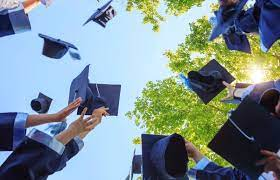                    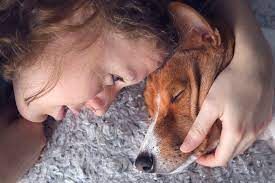                    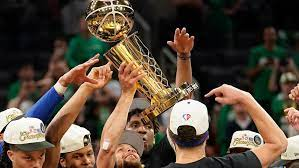 

We remember these occurances as a continuous sequence of experiences; however, they are represented in our minds as discrete episodes, or events, that are woven together to paint the complete picture. 

Events are the building blocks of our ability to remember context-specific information. Yet, it is currently unknown how the beginnings and ends of events are marked as distinct from one another to differentiate between separate occasions. 

Determining the mechanisms behind the separation of events will help to better understand the sequences that promote strong memory as well as those that relate to poor memory.

**Cognitive boundaries shape the transformation from continuous experience to distinct events**

Just as spatial boundaries help us to differentiate between different points in space, cognitive boundaries are suggested to help us differentiate between different points in time. Specifically, cognitive boundaries are thought to bookend event-specific representations of our experiences. 

Neural data has shown large-scale patterns of activity changes in the human brain surrounding event boundaries. While these findings support the notion that cognitive boundaries are the mechanism that separates events in our minds, many questions remain, such as:

- What is the relationship between cognitive boundaries and components of memory?

- What are the underlying neural mechanisms of cognitive boundaries?

This study was the first that aimed to answer these questions with single-cell level analyses in humans. This methodology afforded higher spacial and temporal resolution than has been achieved previously. 

## Methodology

How can we best answer the questions stated above? 

What is the relationship between cognitive boundaries and components of memory?

Subjects completed a three-part memory task to test the relationship between cognitive boundaries and encoding, scene recognition, and time discrimination.

Part 1: Encoding. Subjects watched video clips with three boundary conditions. 

- No boundary (NB): A continuous video clip

- Soft boundary (SB): A clip that cuts to a scene from the same movie

- Hard boundary (HB): A clip that cuts to a scene from a different movie

Part 2: Scene recognition. Single frames of clips were shown to subjects. Some frames were from clips shown in encoding, some frames were novel.

- Subjects were asked to identify whether they had seen the frames before ("old") or not ("new")

- Subjects were asked to rate how confident they were in their selection on a Likert scale

Part 3: Time discrimination. In each trial, two frames separated by wither NB, SB, or HB extracted from the same video clip were shown to subjects.

- Subjects were asked to indicate which of the frames occured first (earlier in time) in the videos watched during encoding.

What are the underlying neural mechanisms of cognitive boundaries?

- This inquiry was answered by recording single-neuron activity from subjects while completing the three-part memory task

- Recordings from the medial temporal lobe (MTL) were primarily used in analyses

- Neural mechanisms investigated included: spike firing rates and latencies, mean resultant length (MRL) for theta band phases of spikes, spike density estimates from all recorded MTL cells across all subjects to determine neural state trajectories, and the size of state shifts as a function of time

### Requirements

All data was stored in Neurodata Without Borders (NWB) format. Each NWB file contains the complete data and metadata for a single session from a single subject. 

- Download [MatNWB interface library](https://neurodatawithoutborders.github.io/matnwb/#setup): Used to read and write NWB files with MATLAB

- [Dataset](https://dandiarchive.org/dandiset/000207/0.220721.1915/files?location=) from one subject obtained from DANDI. The subject file used in this script is 'sub-1_ses-1_ecephys+image.nwb' found [here](https://dandiarchive.org/dandiset/000207/0.220721.1915/files?location=sub-1). 

## Data Preparation and Exploration

Steps must be taken to prepare the data for analyses and explore the dataset before we can begin to answer our research questions.

### 1. Set path structure and add paths

% Path to NWB data file(s)
basePath.data = "C:\Users\darwinm\Documents\MATLAB\DandiDownload_000207";

% Path to matNWB library
basePath.matNWB = "C:\Users\darwinm\Documents\MATLAB\matnwb";
    % Add path for matNWB library 
    addpath(genpath(basePath.matNWB));

### 2. Select subject NWB file

Set the subject ID and session number to plot. Both the subject ID and session number used in this live script is `1`. 

CBID = 19;
sessionNum = 1;

### 3. Import and explore the NWB file

The function `nwbRead` from the matNWB library is used to read files into MATLAB

fName_in = "sub-" + num2str(CBID) + filesep + "sub-" + num2str(CBID) + ...
"_ses-" + num2str(sessionNum) + "_ecephys+image.nwb";
   
% Import file
nwbData = nwbRead(fullfile(basePath.data, filesep, fName_in));

**What is in the NWB file?**

This NWB file contains data and metadata for a single session of an experiment for a single subject.

We will be extracting neural data from the `general_extracellular_ephys_electrodes` and the `units `objects within the NWB file to conduct our analyses.

`general_extracellular_ephys_electrodes` 

- Channel IDs

- Names of brain areas

`units`

- Spike data + indexes

- Electrodes

- Cluster groups

Let's explore the file contents with [nwbTree](https://github.com/NeurodataWithoutBorders/matnwb/blob/master/%2Butil/nwbTree.m), a [utility function](https://github.com/NeurodataWithoutBorders/matnwb/tree/master/%2Butil) included in the MatNWB interface library. nwbTree is a pop-up user interface that incorporates the Matlab [uitree function](https://www.mathworks.com/help/matlab/ref/uitree.html) into the [HDMF utility module](https://hdmf.readthedocs.io/en/stable/hdmf.utils.html) to be used with NWB files. With this tool, you can browse through the structure of the file to find where the data and metadata are located that you wish to extract.

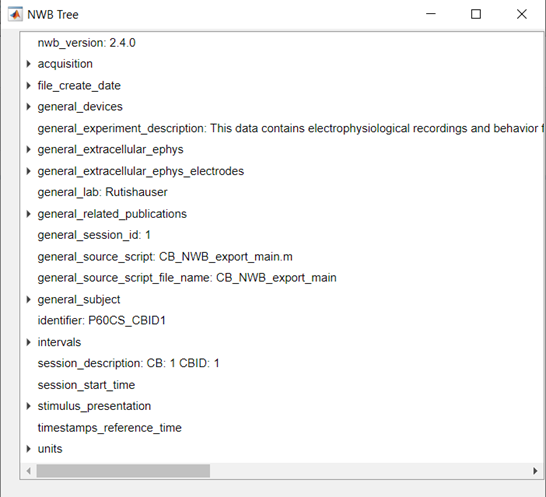

Press the button below if you'd like to view the NWB tree for this file.

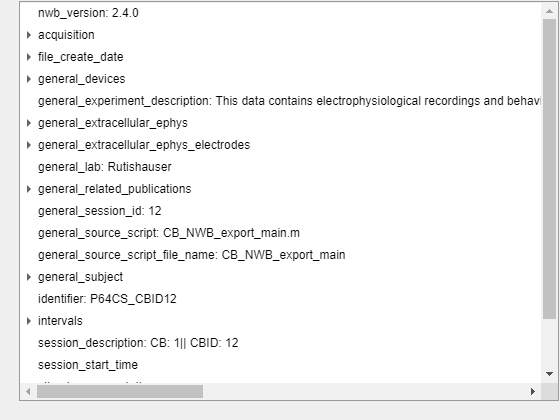

 

util.nwbTree(nwbData);

You can also hover over a variable name in this live script for a small pop-up that reveals the variable contents.

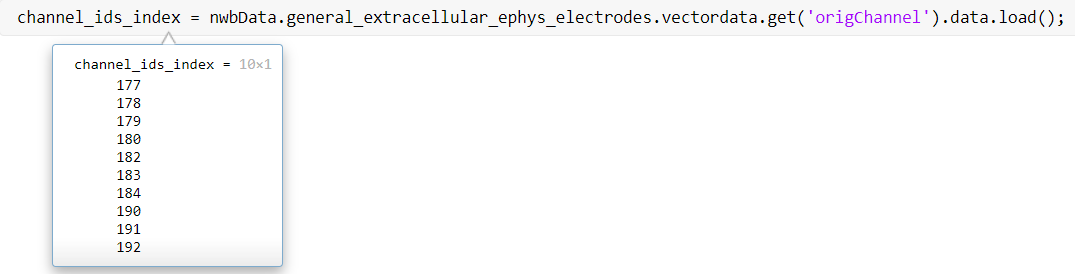

### 4. Load neural data into MATLAB from NWB file

**What neural data will we need to extract? **

Spike data

all_spike_data = nwbData.units.spike_times.data.load();
spike_data_indexes = nwbData.units.spike_times_index.data.load();

Channel IDs 

channel_ids_index = nwbData.general_extracellular_ephys_electrodes.vectordata.get('origChannel').data.load();

Electrodes

cell_electrodes = nwbData.units.electrodes.data.load();

Names of brain areas

brain_areas_index = nwbData.general_extracellular_ephys_electrodes.vectordata.get('location').data.load;

Cluster groups

clusterIDs = nwbData.units.id.data.load;   % All available ID's (clusters)

**Now, use this data to create variables we will need for analyses **

elec_index = cell_electrodes+1; % +1 because the first value of 'cell_electrodes' = 0

Match the channel IDs to the electrode

channel_ids = channel_ids_index(elec_index);

Match the brain area name to the electrode

brain_areas = brain_areas_index(elec_index,:);

## Reproducing Key Figures

A series of analyses were conducted to determine 1) the relationship between cognitive boundaries and components of memory and 2) the underlying neural mechanisms of cognitive boundaries. 

### **Fig. 3: Boundary cells and event cells demarcate different types of episodic transitions.**

***Are there MTL neurons that exhibit changes in activity following cognitive boundaries during encoding?***

What this information would tell us: Answering this question will help us to understand what is happening at the level of single neurons when cognitive boundaries are introduced. Are there specific cells that respond differently to event boundaries? Let's explore and plot the data to find out.

In the following sections, we will determine if there are cells that respond differently to NBs, SBs, or HBs. 

#### Figure 3a

We will first create the raster plot for **Figure 3a**. Raster plots are helpful to visualize the frequency of spike firing to examine the trial-by-trial variability in responses. This raster plot will detail neuronal responses from a boundary cell from the hippocampus during the encoding stage of the behavioral task.

Finish setting the plot parameters.

%  Resolution of raster plot
bin_width_raster = 0.01; % default is 0.01=10ms

bin_width_fr = 0.2;      % default is 0.2=200ms per bin

**For each selected cell, locate spikes within each cluster and plot**

This section utilizes the `nwb_read_unit.m` function and the `fig3a_reproduction.mlx` live function.

Create the variable for the number of clusters in the data. The first value in `clusterIDs` is `0`, so we subtract 1 to calculate the true number of clusters.

numClust = (height(clusterIDs)-1);

Decide which cluster you'd like to plot. Change the cluster number to see what the plot looks like in the figure 3a replication just below.

cluster2plot = 1;

Now, we locate the spikes within this cluster. Since the first value in `clusterIDs `is `0`, we add 1 in each of the variables created below for the cluster of interest. Then, use the first live function `fig3a_reproduction` to create a raster plot of the cell.

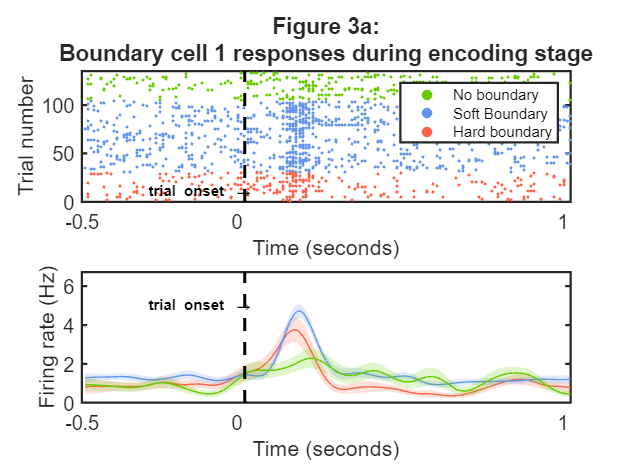

% Locate spikes that belong to this cluster
    timestampsOfCell = nwb_read_unit(nwbData.units.spike_times_index, ...
        nwbData.units.spike_times, clusterIDs(cluster2plot)+1); % Timestamps of cluster
    channelid =  channel_ids((cluster2plot)+1);
    cellNr = clusterIDs((cluster2plot)+1); % Cell number
    brainAreaOfCell = brain_areas((cluster2plot)+1,:);
    currentCell = cellNr;

% Raster plot of cell
    % Encoding, boundary aligned
[boundary_time_reordered, bins_n_raster, fr_per_bin_HB, fr_per_bin_avg_HB, n_data] = fig3a_reproduction...
    (nwbData, timestampsOfCell, bin_width_raster, bin_width_fr, cluster2plot);

The result is the raster plot and a spike tuning curve for the encoding period, boundary aligned, for the cluster of your choice. Several variables calculated within this live function are outputted to be used for subsequent steps in the analyses.

**Key: **The trials with NB are in green, trials with SB are in blue, and trials with HB are in red. 

**Figure 3a: Discussion**

The raster plot shows us that some cells in the MTL responded more to SB and HB than NB. Specifically, this subset had increased firing rate within 300 ms following both SBs and HBs but not NBs. These cells are termed boundary cells.

Although not shown in this figure subpanel, there were another subset of cells that were only responsive (i.e., increased firing rate) following HBs compared to SBs and NBs (Figure 3e). These cells are termed event cells. 

***Note: ***The NWB files currently available within the DANDI database contain the data needed to reproduce the figure panels pertaining to boundary cells, and not event cells. Thus, this live script will reproduce panels of Figure 3 that pertain only to boundary cell analyses, but discussions of the significance of event cells will be included. 

#### Figure 3c

Next, we will create the plot for **Figure 3c** using `imagesc`. Whereas the raster plot generated in Figure 3a allowed us to visualize how the firing rate of one cell, or cluster, differed depending on the boundary type, this type of plot will allow us to visualize how the firing rate of all clusters differed depending on boundary type. 

`imagesc` creates an `m`-by-`n` grid of pixels from the array `C`. In this example, we will create a single array with the firing rates of all clusters (`C`). Within `C`, each row (`m`), is a single cluster, and each pixel (`n`) within each row is a single trial. 

Several variables created during the reproduction of Figure 3a will be used here as the input arguments for the function below. If you wish to change the values of these parameters do so now. Otherwise, the accompanying function will use the values previously computed.

Run the function below to reproduce Figure 3c. 

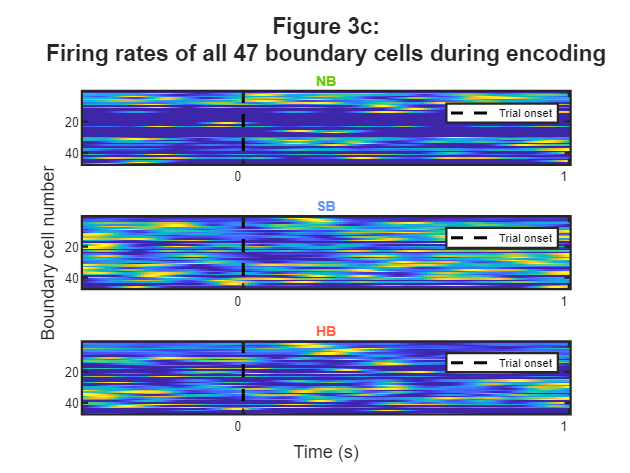

fr_avg_HB_zScore =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1680    0.1528    0.1313    0.0988    0.0737    0.0406    0.0268    0.0036   -0.0050   -0.0191   -0.0419   -0.0612   -0.1133   -0.1784   -0.2471   -0.3363   -0.4206   -0.4717   -0.5382   -0.5886   -0.6207   -0.6484   -0.6449   -0.6402   -0.6372   -0.6218   -0.6064   -0.5629   -0.5367   -0.5200   -0.4809   -0.4416   -0.3929   -0.3153   -0.2328   -0.1312   -0.0233    0.0743    0.2037    0.3310    0.4368    0.5354    0.6058    0.6623    0.7036    0.6918    0.6635    0.5951

[fr_avg_HB_zScore] = fig3c_reproduction(bins_n_raster, ...
    nwbData, numClust, clusterIDs, n_data, boundary_time_reordered, bin_width_raster)

**Figure 3c: Discussion**

Whereas Figure 3a showed us how the firing rate of *one* boundary cell changed depending on boundary type, Figure 3c shows us how *all *boundary cells responded. This plot illustrates that overall, the boundary cells had increased firing rate following both SBs and HBs but not NBs. 

**Main takeaway of Figures 3a and 3c:**** Two types of cells within the MTL were differently affected by cognitive boundaries.**

Boundary cells were responsive to both HBs and SBs, but not NBs (Figure 3a and 3c, while event cells were only responsive to HBs (Figure 3e and 3g).

These findings help to paint a picture of how specific events are formed and coded for within the brain. In the memory task, HBs were simulated by showing a clip of one movie followed by a clip of a completely different movie to represent an abrupt change in stimulus content and context. The finding that event cells were only responsive to HBs suggests that they function to detect a stark disruption of the conceptual narrative, or in other words, the transition between two different episodes. 

While the differences between boundary cells and event cells are evident from the figure panels already discussed, let's think about how else we can visualize the differences between the two types to deepen our understanding. 

#### Figure 3i

We saw in the Figure 3 subpanels already discussed that the firing rates of event cells and boundary cells appear to differ the most in response to hard boundaries. Specifically, following hard boundaries, boundary cells reach their peak firing rate sooner than event cells. Figure 3i and 3j will hone in on the hard boundary experimental condition to further explore this difference in firing rates between the two types of cells. 

To visualize the difference in firing rates between event cells and boundary cells following hard boundaries, we will first plot the firing rate of the boundary cell cluster previously chosen to plot in Figure 3a. With event cell data, we may do the same for event cells to visually compare the two types.

Run the function below to plot the z-scored firing rate of one of the boundary cell clusters as a function of time following a hard boundary. Several input variables from previous calculations are utilized.

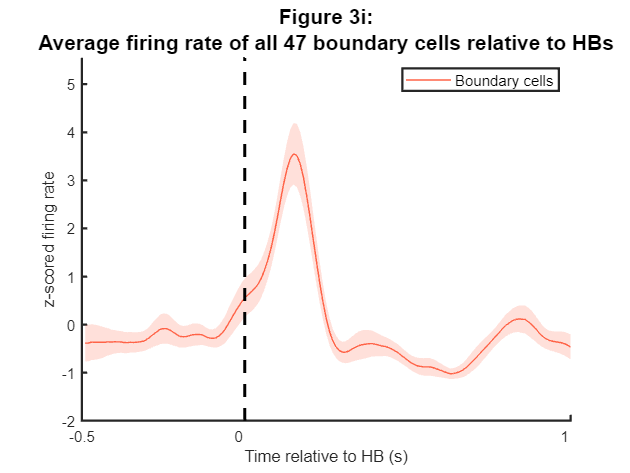

fig3i_reproduction(bin_width_raster, fr_per_bin_avg_HB, fr_per_bin_HB, numClust);

**Figure 3i: Discussion**

Although not shown in this partial reproduction of Figure 3i, when plotting the average firing rate of an event cell cluster, the boundary cell firing rate has a shorter latency compared to the event cell firing rate. 

We will continue to explore this finding by plotting the firing rates of all clusters in a similar fashion in Figure 3j, after which we will discuss the implications.

#### Figure 3j

Whereas Figure 3i demonstrated the differences in firing rates for one boundary cell compared to one event cell, Figure 3j will examine these differences across all boundary and event cells with a swarmplot. Swarmplots are useful for illustrating the distribution and patterns across all observed data points. 

Use this function to create a swarmplot of all boundary cells.

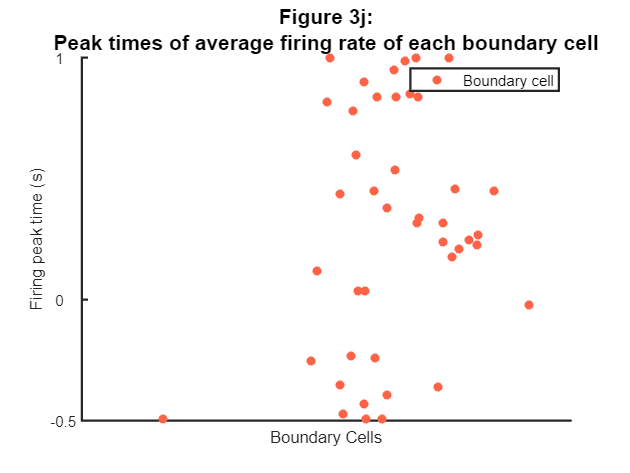

fig3j_reproduction(fr_avg_HB_zScore, bin_width_raster);

**Figure 3j: Discussion**

Although again not shown in this partial reproduction, the plot aims to demonstrate that in response to HBs, boundary cells have a quicker peak firing time than event cells. 

**Main takeaway of Figures 3i and 3j:**** Two types of cells within the MTL were differently affected by hard boundaries.**

Boundary cells both fired quicker (Figure 3i) and had a quicker peak firing time (Figure 3j) relative to HBs compared to event cells.

These findings help us understand the different roles of event cells and boundary cells. To reiterate from above, in the memory task, HBs were simulated by showing a clip of one movie followed by a clip of a completely different movie to represent an abrupt change in stimulus content and context. The finding that the firing rate of event cells were later in time compared to boundary cells suggests that there are two cellular responses to HBs. The earlier response from boundary cells may signify perceptual changes in stimuli influenced from visual areas while the later response from event cells may indicate an internal comparison between the predicted and recieved input. Together, both types of cells allow for the transformation of our experiences into distinct episodes to be later retrieved in an effort to help us navigate the world.

## References

[1] DANDI dataset ID: 000207. 

Cite as: Zheng, Jie; Schjetnan, Andrea; Yebra, Mar; Gomes, Bernard; Mosher, Clayton; Kalia, Suneil; Valiante, Taufik; Mamelak, Adam; Kreiman, Gabriel; Rutishauser, Ueli (2022) Data for: Neurons detect cognitive boundaries to structure episodic memories in humans (Zheng et al., 2022, Nat Neuro in press) (Version 0.220721.1915) [Data set]. DANDI archive. https://doi.org/10.48324/dandi.000207/0.220721.1915

[2] Zheng, J., Schjetnan, A.G.P., Yebra, M. *et al.* Neurons detect cognitive boundaries to structure episodic memories in humans. *Nat Neurosci* **25**, 358–368 (2022). [https://doi.org/10.1038/s41593-022-01020-w](https://doi.org/10.1038/s41593-022-01020-w)

## About the Author

This live script and accompanying live functions were written by [Marielle L. Darwin, PhD](https://www.linkedin.com/in/marielledarwin/). At the time of this writing, Marielle is a Clinical Research Associate at University of Colorado Anschutz Medical Campus in Aurora, CO, USA. 